data = readtable('train_data.csv');
test = readtable('test_low_frequency.csv');
load("yval_sinesweep.mat")
load("yval_multisine.mat")
load("uval_sinesweep.mat")
load("uval_multisine.mat")

uEst = num2cell(data.u');
uVal = num2cell(test.u');
uTest1 = num2cell(uval_multisine);
uTest2 = num2cell(uval_sinesweep);
yEst = num2cell(data.y');
yVal = num2cell(test.y')

yVal = 1×1000 cell array
    {[0]}    {[1.8527e-07]}    {[1.4595e-06]}    {[4.8090e-06]}    {[1.1033e-05]}    {[2.0677e-05]}    {[3.3988e-05]}    {[5.0911e-05]}    {[7.1085e-05]}    {[9.3925e-05]}    {[1.1865e-04]}    {[1.4439e-04]}    {[1.7022e-04]}    {[1.9525e-04]}    {[2.1872e-04]}    {[2.3999e-04]}    {[2.5862e-04]}    {[2.7442e-04]}    {[2.8737e-04]}    {[2.9769e-04]}    {[3.0581e-04]}    {[3.1222e-04]}    {[3.1759e-04]}    {[3.2268e-04]}    {[3.2821e-04]}    {[3.3490e-04]}    {[3.4338e-04]}    {[3.5414e-04]}    {[3.6756e-04]}    {[3.8379e-04]}    {[4.0285e-04]}    {[4.2456e-04]}    {[4.4857e-04]}    {[4.7444e-04]}    {[5.0155e-04]}    {[5.2934e-04]}    {[5.5716e-04]}    {[5.8441e-04]}    {[6.1054e-04]}    {[6.3510e-04]}    {[6.5774e-04]}    {[6.7822e-04]}    {[6.9647e-04]}    {[7.1246e-04]}    {[7.2636e-04]}    {[7.3850e-04]}    {[7.4923e-04]}    {[7.5900e-04]}    {[7.6830e-04]}    {[7.7765e-04]}    {[7.8757e-04]}    {[7.9854e-04]}    {[8.1098e-04]}    {[8.2522e-04]}    {[8.4150

yTest1 = num2cell(yval_multisine);
yTest2 = num2cell(yval_sinesweep);

rng(42);
d1 = [1:4];
d2 = [1:25];
narx_net = narxnet(d1,d2,[4, 4]);
narx_net.divideFcn = '';
narx_net.trainParam.min_grad = 1e-11;
[p,Pi,Ai,t] = preparets(narx_net,uEst,{},yEst);

narx_net = train(narx_net,p,t,Pi);

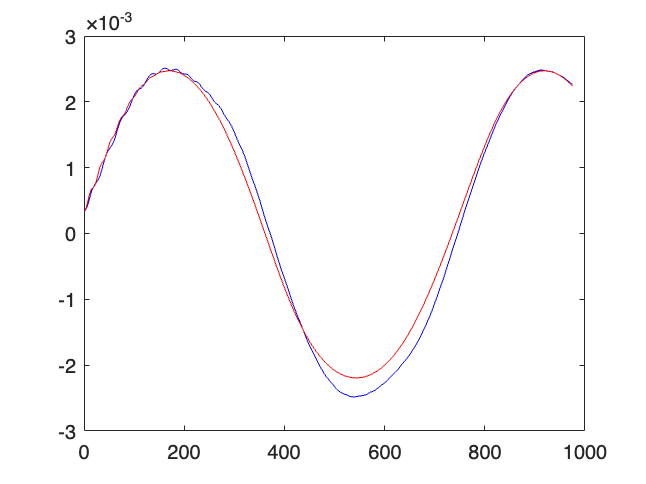

y1 = yVal(1:1000);
u1 = uVal(1:1000);
narx_net_closed = closeloop(narx_net);
[p1,Pi1,Ai1,t1] = preparets(narx_net_closed,u1,{},y1);
yp1 = narx_net_closed(p1,Pi1,Ai1);
TS = size(t1,2); 
plot(1:TS,cell2mat(t1),'b',1:TS,cell2mat(yp1),'r')

writecell(yp1', 'NARX_lowfrequency.csv')

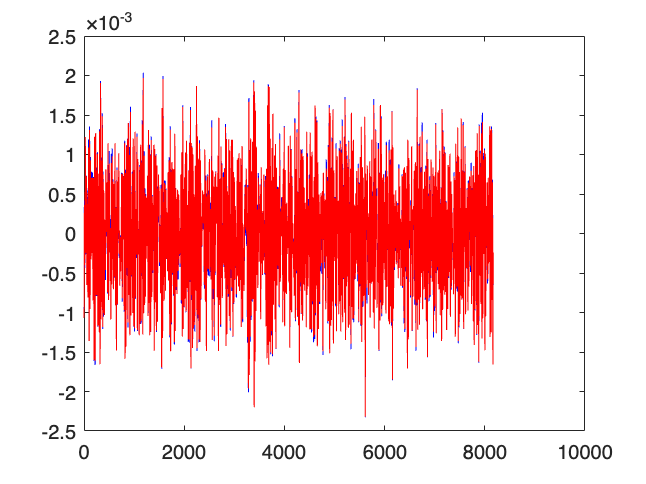

y2 = yTest1(1:8192);
u2 = uTest1(1:8192);
[p2,Pi2,Ai2,t2] = preparets(narx_net_closed,u2,{},y2);
yp2 = narx_net_closed(p2,Pi2,Ai2);
TS2 = size(t2,2); 
plot(1:TS2,cell2mat(t2),'b',1:TS2,cell2mat(yp2),'r')

writecell(yp2', 'NARX_multisine.csv')

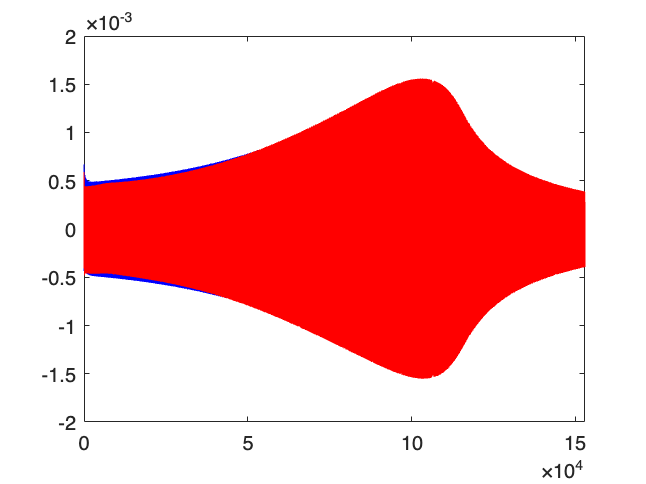

y3 = yTest2(1:153000);
u3 = uTest2(1:153000);
[p3,Pi3,Ai3,t3] = preparets(narx_net_closed,u3,{},y3);
yp3 = narx_net_closed(p3,Pi3,Ai3);
TS3 = size(t3,2); 
plot(1:TS3,cell2mat(t3),'b',1:TS3,cell2mat(yp3),'r')

writecell(yp3', 'NARX_sinesweep.csv')